Units in this program: ft / s / lb / radians / mWH

## Variables

Constants

clear variables;
c.g = 32; % Gravity in silly units
% Upper range weights, in lb
c.weightDoll = 0.1;
c.weightPatient = 0.28;
c.timeLimit = 300;
c.distance0 = 2000;

Scalar Presets

s.batteryCapacity = 96;
s.weightMedicalSupplyCabinet = 4;
s.nPassengersM3 = 20;
s.speedM2 = 30;
s.speedM3 = 30;
s.timeTakeOff = 24;
s.fLoadFactor = 3;

Variable Presets

v.batteryCapacity = linspace(20, 100, 16);
v.weightMedicalSupplyCabinet = linspace(1,5,16);
v.nPassengersM3 = linspace(1, 20, 16);
v.speedM2 = linspace(6, 50, 16);
v.speedM3 = linspace(6, 50,16);
v.timeTakeOff = linspace(6, 100, 16);
v.fLoadFactor = linspace(2, 8, 16);

Selection

props = ["batteryCapacity","weightMedicalSupplyCabinet","nPassengersM3","speedM2","speedM3","timeTakeOff","fLoadFactor"];
xdim = props(2);
ydim = props(3);
xdimIndex = find(strcmp(xdim, props));
ydimIndex = find(strcmp(ydim, props));
if (xdimIndex < ydimIndex)
    tempdim = ydim;
    ydim = xdim;
    xdim = tempdim;
end
dims = [xdim ydim];
% Definite independent
batteryCapacity = chooseVariableOrConstant(dims, "batteryCapacity", s, v);
weightMedicalSupplyCabinet = chooseVariableOrConstant(dims, "weightMedicalSupplyCabinet", s, v);
nPassengersM3 = chooseVariableOrConstant(dims, "nPassengersM3", s, v);
speedM2 = chooseVariableOrConstant(dims, "speedM2", s, v);
speedM3 = chooseVariableOrConstant(dims, "speedM3", s, v);
timeTakeOff = chooseVariableOrConstant(dims, "timeTakeOff", s, v);
fLoadFactor = chooseVariableOrConstant(dims, "fLoadFactor", s, v);

% Intermediate calculations
weightM2 = weightMedicalSupplyCabinet + 4 * c.weightDoll + c.weightPatient;
weightM3 = (nPassengersM3 + 2) * c.weightDoll;
% none

% The magic function that makes it work
tic;
[CB, WMSC, NP3, V2, V3, TTO, FLF] = ndgrid(batteryCapacity, weightMedicalSupplyCabinet, nPassengersM3, speedM2, speedM3, timeTakeOff, fLoadFactor);

% Compute M2
W2 = 4 * c.weightDoll + c.weightPatient + WMSC;
RB2 = V2.^2 ./ (c.g * sqrt(FLF.^2 - 1));
D2 = c.distance0 + 4 * pi * RB2;
TL2 = D2 ./ V2;
T2 = 3 * TL2 + TTO;
M2 = W2 ./ T2;

% Compute M3
RB3 = V3.^2 ./ (c.g * sqrt(FLF.^2 - 1));
D3 = c.distance0 + 4 * pi * RB3;
TL3 = D3 ./ V3;
NL = (c.timeLimit - TTO) ./ TL3;
if (true)
    NL = floor(NL);
end
M3 = NL .* NP3 ./ CB;

Score = M2 + M3 + 5;
fprintf('Computed %d elements', numel(Score));

Computed 256 elements

toc;

Elapsed time is 0.018607 seconds.


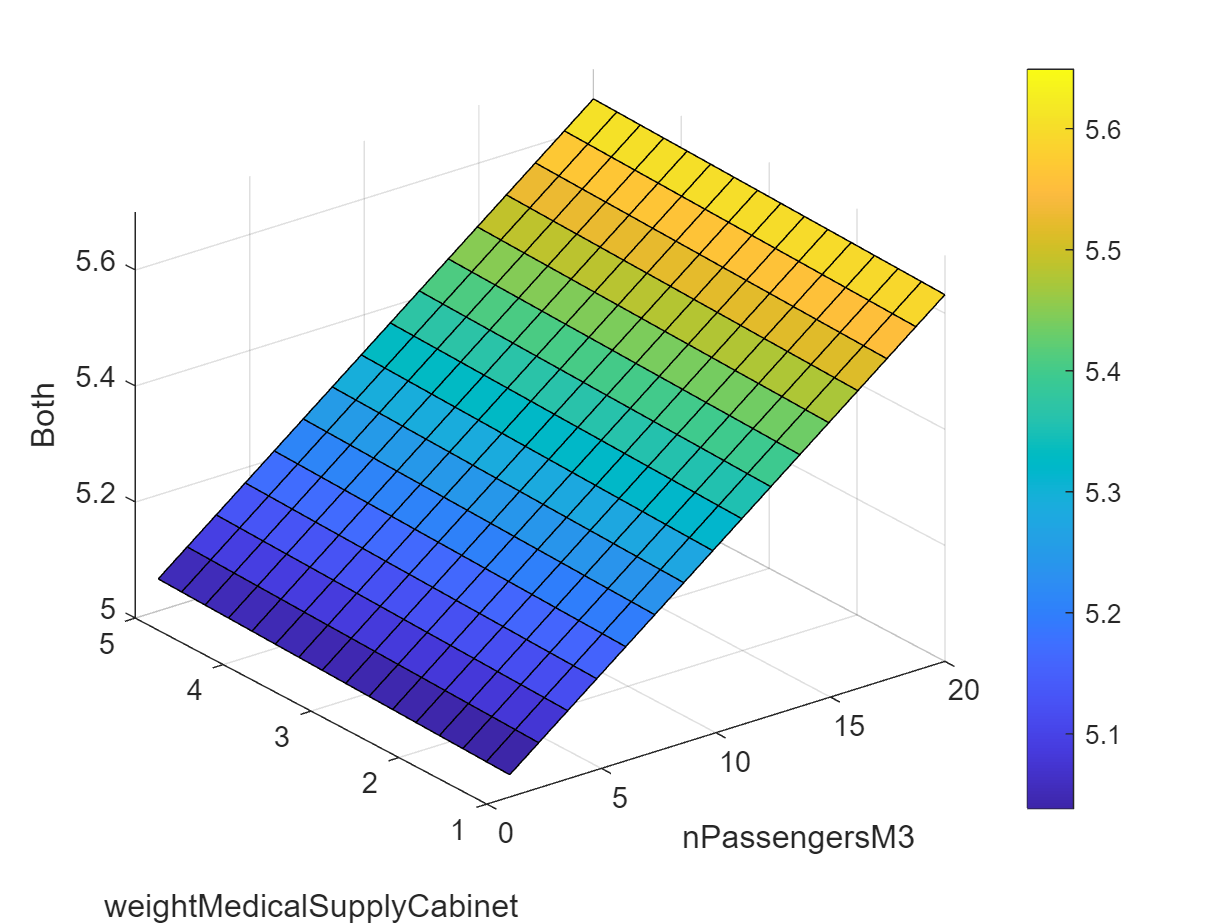

% Create a surface plot
type  = ("Both");
switch (type)
    case "M2"
        Z = M2;
    case "M3"
        Z = M3;
    otherwise
        Z = Score;
end
if (xdim ~= ydim)
    Z = squeeze(Z);
    surf(v.(xdim), v.(ydim), Z);
    colorbar;
    
    xlabel(xdim);
    ylabel(ydim);
    zlabel(type);
else
    plot(v.(xdim), Z);
    xlabel(xdim);
    ylabel(type);
end



% Harry do we really, really have to use the imperial system. 